## Analysis of a blood vessel network 

**ODE Model**

Blood vessels are often represented by lumped parameter models. In this description, a vessel is represented as a zero-dimensional chamber, having a pressure, compliance, and resistance to flow. Each vessel is modeled by an ordinary differential equation (ODE):

  
$$c \frac{dp}{dt} = \text{flow in} - \text{flow out}$$


where $p = p(t)$ is the pressure in the vessel.

The flow in depends on the pressure in the upstream vessel. The flow out depends similarly on the downstream vessel pressure. For example, if there is only one vessel upstream and downstream:

  
$$c \frac{dp}{dt} = \frac{p_{upstream} - p}{r_{in}} - \frac{p - p_{downstream}}{r_{out}}$$


Modeling a blood vessel network typically requires many equations of this form. Consider the (relatively small) system of 5 connected vessels shown.

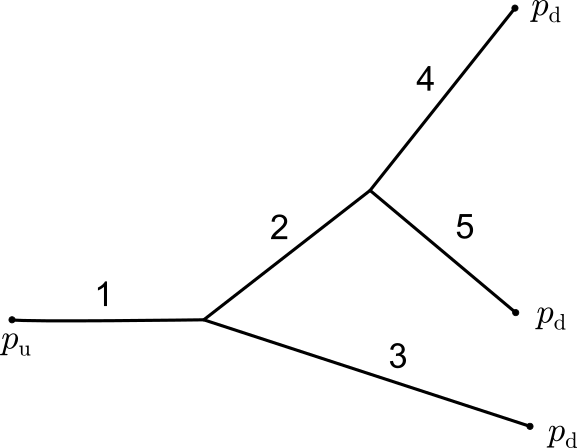

*Network of 5 connected vessels.*

To describe this system, you can define variables and constants for each vessel.

- $p_i = p_i(t)$: Pressure in the $i^{th}$ vessel at time $t$

- $c_i$: Compliance of the $i^{th}$ vessel

- $r_i$: Resistance of the $i^{th}$ vessel

The pressure entering the system is a constant upstream pressure, $p_u$. At the downstream end, a constant pressure $p_d$ is assumed. Resistance to flow out of the network is assumed to be a single constant value, $r_d%$$.

Under this description, the ODEs for the vessel pressures are:

    
$$c_1 \frac{dp_1}{dt} = \frac{p_u - p_1}{r_1}  - \frac{p_1 - p_2}{r_2} - \frac{p_1 - p_3}{r_3}$$


    
$$c_2 \frac{dp_2}{dt} = \frac{p_1 - p_2}{r_2} - \frac{p_2 - p_4}{r_4} - \frac{p_2 - p_5}{r_5}$$


    
$$c_3 \frac{dp_3}{dt} = \frac{p_1 - p_3}{r_3} - \frac{p_3- p_d}{r_d}$$


    
$$c_4 \frac{dp_4}{dt} = \frac{p_2 - p_4}{r_4} - \frac{p_4 - p_d}{r_d}$$


    
$$c_5 \frac{dp_5}{dt} = \frac{p_2 - p_5}{r_5} - \frac{p_5-p_d}{r_d}$$


**Matrix representation of the ODE system**

Defining the solution vector $\mathbf{p}$:

    
$$\mathbf{p} = \left(\matrix{p_1 \cr p_2 \cr p_3 \cr p_4 \cr p_5 }\right)$$


allows the ODE system to be written in matrix form:

    $\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p} + \mathbf{f}$.

** Exercise**. Derive the form of the matrices $\mathbf{C}$, $\mathbf{R}$, and the constant vector $\mathbf{f}$. You can do this by hand or using symbolic math operations described in the following section.

**Deriving a matrix form using symbolic math**

You can derive the coefficient matrix $\mathbf{R}$ and constant vector $\mathbf{f}$ by hand, but this task tedious and prone to errors. As an alternative, you can use the Symbolic Math Toolbox to derive the matrix form of the system. An example of this process is shown below.

** Example.** Consider the example system of equations

    
$$\begin{array}{l}
\frac{dy_1}{dt} = c_5 -c_3 \,y_4 +y_1 \,{\left(c_1 +c_2 \right)}\\
\frac{dy_2}{dt} =  -\frac{y_2 \,y_5 }{c_3 }\\
\frac{dy_3}{dt} = c_7 -\frac{y_3 \,{\left(c_2 -c_6 \right)}}{c_3 }\\
\frac{dy_4}{dt} = c_2 -c_1 \,y_1 +y_4 \,{\left(c_7 +c_8 \right)}\\
\frac{dy_5}{dt} = c_8 -c_6 -c_{10} \,y_1 +y_3 \,{\left(c_1 +c_9 \right)}
\end{array}

$$


Rewrite the system in matrix form 

    $\frac{d\mathbf{y}}{dt} = \mathbf{Cy} + \mathbf{d}$. 

1. Define the RHS of the equation using symbolic variables.

y = sym("y",[5,1]);
c = sym("c",[10,1]);
RHS = [(c(1)+c(2))*y(1) + c(5)-c(3)*y(4); 
        y(2)/c(5) - (c(3)) - c(5)*y(5);
       (c(6) - c(2))/(c(3))*y(3) + c(7);
       (c(7)+c(8))*y(4) + c(2)-c(1)*y(1); 
       (c(1) + c(9))*y(3) - y(1)*c(10) - c(6) + c(8)];
expand(RHS)

2. Set the RHS equal to zero (we are not solving for the equilibrium solutions, but rather using this to factor the system).

eqns = RHS == 0

3. The  [`equationsToMatrix`](https://www.mathworks.com/help/symbolic/equationstomatrix.html) function used with the syntax

solves for the factorization of a system in the form $\mathbf{Ax} = \mathbf{b}$. This is used to factor the system here in terms of $\mathbf{y}$:

[A,b] = equationsToMatrix(eqns,y)

4. The final step is to recognize that the factorization has produced the negative of $\mathbf{d}$. This implies the matrix form of the system is

    
$$\frac{d\mathbf{y}}{dt} = \mathbf{Cy} + \mathbf{d}$$


with

C = A
d = -b

5. You can verify that the system is in the correct form by multiplying the RHS.

C*y + d

** Exercise**. Rewrite the blood vessel network ODE system 

    
$$c_1 \frac{dp_1}{dt} = \frac{p_u - p_1}{r_1}  - \frac{p_1 - p_2}{r_2} - \frac{p_1 - p_3}{r_3}$$


    
$$c_2 \frac{dp_2}{dt} = \frac{p_1 - p_2}{r_2} - \frac{p_2 - p_4}{r_4} - \frac{p_2 - p_5}{r_5}$$


    
$$c_3 \frac{dp_3}{dt} = \frac{p_1 - p_3}{r_3} - \frac{p_3- p_d}{r_d}$$


    
$$c_4 \frac{dp_4}{dt} = \frac{p_2 - p_4}{r_4} - \frac{p_4 - p_d}{r_d}$$


    
$$c_5 \frac{dp_5}{dt} = \frac{p_2 - p_5}{r_5} - \frac{p_5-p_d}{r_d}$$


in matrix form 

    $\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p} + \mathbf{f}$.

You can use the Symbolic Math Toolbox to derive $\mathbf{R}$ and $\mathbf{f$. Symbolic vectors of constants and variables are defined below for you to use in your computations.

p = sym("p",[5,1]); % pressures
c = sym("c",[5,1]); % compliances
r = sym("r",[5,1]); % resistances
syms p_u p_d r_d    % upstream and downstream constants

Write code that computes $\mathbf{C}$, $\mathbf{R}$, and $\mathbf{f}$ here.

RHS = [  (p_u - p(1))/r(1) - (p(1)- p(2))/r(2) - (p(1)-p(3))/r(3);
         (p(1) - p(2))/r(2) - (p(2)-p(4))/r(4) - (p(2)-p(5))/r(5);
         (p(1)-p(3))/r(3) - (p(3)-p_d)/r_d;
         (p(2)-p(4))/r(4) - (p(4)-p_d)/r_d;
         (p(2)-p(5))/r(5) - (p(5)-p_d)/r_d                   ];
RHS = expand(RHS)
eqns = RHS == 0
[A,b] = equationsToMatrix(eqns,p);
R = A
f = -b
C = diag(sym("c",[5,1]))

You can view and/or use the solution by clicking the checkbox below.

useSolution = true; % Show and define variables for the solution
if(useSolution)
    [R,f,C] = vesselMatrixForm();
end

**Numerical solution to the ODE system**

The ODE system can be solved for a given set of constants in MATLAB using a numeric ODE solver. 

  **Try. ** 

- Run this section to define a parameter set and solve the system.

- Adjust the parameters and/or initial conditions and solve the system again.

% Define the vessel resistances
r = [1 2 1 5 1];
% Define the vessel compliances
c = [2 0.4 0.1 2 3];
% Define the other constants
pu = 10;   % Upstream pressure
pd = 4;    % Downstream pressure
rd = 0.5;  % Outflow resistance
% Initial conditions
p0 = [0 0 0 0 0];
% Simulation duration
tf = 10;
 

odeFunc = @(t,p)vesselODEFunc(t,p,c,r,pu,pd,rd);
[t,p] = ode45(odeFunc,[0,tf],p0);
figure("position",[1,1,800,400])
plot(t,p)
legend("p_{" + strsplit(num2str(1:5)) + "}",'Location','EastOutside')
title("Vessel pressures")
xlabel('t')
ylabel('p(t)')

 **Reflect**

- Regardless of the parameters and initial conditions, what is true about the long-term behavior of the system? 

- Does this long-term behavior make physical sense?

**Steady state solution**

The numeric solution of the ODE system reaches a steady state over time input and output pressures are constant. You can solve for this state.

** Exercise**. Solve for the steady state of the general ODE system (i.e., without specifying the constants).

  **Task**. The system is in a steady state when $\frac{d\mathbf{p}}{dt} = 0$. Solve for the steady state of $\mathbf{p}$ in terms of $\mathbf{C}$, $\mathbf{R}$, and $\mathbf{f}$.

**Solution.**

    
$$\begin{array}{rl}
\mathbf{C} \cdot \mathbf{0}&= \mathbf{R}\mathbf{p} + \mathbf{f}
\\
\mathbf{0} &= \mathbf{R}\mathbf{p} + \mathbf{f}
\\
\mathbf{R}\mathbf{p} &= - \mathbf{f}
\end{array}$$


  **Task**. Use symbolic functions to compute the expanded expression for the steady state $\mathbf{p$. Note that $\mathbf{C}$, $\mathbf{R}$, and $\mathbf{f}$ have been defined in the previous sections.

p_steady = R\-f

** Exercise**. Solve for the steady state of the specific ODE system by performing the tasks.

  **Task**. Create an anonymous function for the symbolic expression in `p_steady` by applying the [`matlabFunction`](https://www.mathworks.com/help/symbolic/matlabfunction.html) function using the syntax

pFunction = matlabFunction(p_steady)

  **Task**. Use the generated function to compute the specific steady state for constants defined above in `r`, `c`, `pu`, `pd`, and `rd`. Note that the order of the function inputs is listed at the beginning of the anonymous function.

pFunction(pd,pu,r(1),r(2),r(3),r(4),r(5),rd)

 **Reflect**

- Does the steady state solution match the long-term behavior of the numeric solution of the ODE?

- Why is the steady state pressure higher in the first vessel ($p_1$) than in the other vessels?

- Try adjusting the constants used in the numeric solution. Does the steady state behavior still match?

- For very large ODE systems, the symbolic method for solving for the steady state is impractical. How would you adjust this workflow so that you could solve for the steady state of a larger system without performing the algebra by hand?

**Stability analysis**

In a typical homogeneous ODE stability analysis, you analyze a linear system in matrix form:

    $\frac{d\mathbf{x}}{dt} = \mathbf{A}\mathbf{x}$,

where $\mathbf{A}$ is a constant coefficient matrix. In this representation, the eigenvalues of $\mathbf{A}$ determine the stability of the solutions. In addition, it can be shown that all the solutions are linear combinations of the eigenvectors $\mathbf{v}_i$:

    
$$\mathbf{x}(t) = \sum_i \alpha_i \mathbf{v}_i e^{\lambda_i t}$$


The value of each eigenvalue $\lambda_i$ determines the stability of that eigenmode. 

- If $\text{Re}(\lambda_i)>0$, the mode grows exponentially

- If $\text{Re}(\lambda_i)<0$, the mode decays exponentially

- If $\text{Re}(\lambda_i)=0$ and $\text{Im}(\lambda_i) \neq 0$, the mode oscillates without growth or decay

** Exercise**. Show that

    
$$\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p} + \mathbf{f}$$


can be written in the form

    $\frac{d\mathbf{u}}{dt} = \mathbf{A}\mathbf{u}$, 

so that a standard linear stability analysis may be used.

The equivalent form of the system is

    
$$\frac{d\mathbf{u}}{dt} = \mathbf{A} \mathbf{u}$$


with $\mathbf{A} = \mathbf{C}^{-1} \mathbf{R}$ and $\mathbf{u} =\mathbf{p} -\mathbf{R}^{-1}\mathbf{f}$. 

** Exercise**. In this exercise, you will perform a linear stability analysis on the blood vessel ODE system.

Specific $\mathbf{C}$, $\mathbf{R}$, and $\mathbf{f}$ are defined here in MATLAB variables `Cs`, `Rs`, and `fs` using the constants from earlier in the example. 

Cs = diag(c)
Rfunc = matlabFunction(R);
Rs = Rfunc(r(1),r(2),r(3),r(4),r(5),rd)
fFunc = matlabFunction(f);
fs = fFunc(pd,pu,r(1),rd)

  **Task**. Define the matrix $\mathbf{A}$ using the constant matrices just defined.

A = inv(Cs)*Rs

  **Task**. Compute the eigen decomposition of $\mathbf{A}$.

[V,D] = eig(A)

 **Reflect**

- Is the system stable for the auxiliary variable $\mathbf{u}$?

- Is the system also stable for the original variable $\mathbf{p}$? Show that your answer is the case using the definition of $\mathbf{u}$: $\mathbf{u} =\mathbf{p} -\mathbf{R}^{-1}\mathbf{f}$. 

- Show that the steady state solution of $\mathbf{p}$ is $-\mathbf{R}^{-1} \mathbf{f}$ using the analysis of $\mathbf{u}$.

Supporting functions for blood vessel network application

function [R,f,C] = vesselMatrixForm()
    p = sym("p",[5,1]); % pressures
    c = sym("c",[5,1]); % compliances
    r = sym("r",[5,1]); % resistances
    syms p_u p_d r_d    % upstream and downstream constants
    RHS = [  (p_u - p(1))/r(1) - (p(1)- p(2))/r(2) - (p(1)-p(3))/r(3);
             (p(1) - p(2))/r(2) - (p(2)-p(4))/r(4) - (p(2)-p(5))/r(5);
             (p(1)-p(3))/r(3) - (p(3)-p_d)/r_d;
             (p(2)-p(4))/r(4) - (p(4)-p_d)/r_d;
             (p(2)-p(5))/r(5) - (p(5)-p_d)/r_d                           ];
    RHS = expand(RHS);
    eqns = RHS == 0;
    [A,b] = equationsToMatrix(eqns,p);
    R = A
    f = -b
    C = diag(sym("c",[5,1]))
end
function dpdt = vesselODEFunc(t,p,c,r,pu,pd,rd)
    dpdt = vesselODE(c(1),c(2),c(3),c(4),c(5),p(1),p(2),p(3),p(4),p(5),pd,pu,r(1),r(2),r(3),r(4),r(5),rd);
end
function vesselODE = vesselODE(c1,c2,c3,c4,c5,p1,p2,p3,p4,p5,p_d,p_u,r1,r2,r3,r4,r5,r_d)
    %    This function was generated by the Symbolic Math Toolbox version 8.6.
    vesselODE = [(p2./r2+p3./r3+p_u./r1-p1.*(1.0./r1+1.0./r2+1.0./r3))./c1;(p1./r2+p4./r4+p5./r5-p2.*(1.0./r2+1.0./r4+1.0./r5))./c2;(p1./r3+p_d./r_d-p3.*(1.0./r3+1.0./r_d))./c3;(p2./r4+p_d./r_d-p4.*(1.0./r4+1.0./r_d))./c4;(p2./r5+p_d./r_d-p5.*(1.0./r5+1.0./r_d))./c5];
end

Suppress unused suggestions

%#ok<*INUSL> 
%#ok<*NASGU> 
%#ok<*NOPRT>
%#ok<*UNRCH> 
%#ok<*DEFNU> 